## Test function: Banded trigonometric problem - 10^3

% Dimension n (multiple of 2)
n = 10^3;  % 10^3;

% Initializations
x0 = zeros(n, 1);

% Generalization of the Brown function 1
f = @(x) banded_trigonometric(x);

% Starting point x0
x0(1) = 0;
for j = 2 : n-1
    x0(j) = 1;
end
x0(n) = 0;


% Expected solution
x_sol = zeros(1, n)';

% Gradient
gradf = @(x) banded_trigonometric_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 10000;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 1;  % initial step-length
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax     step_k    tolgrad      c1      rho    btmax
    _____    ______    _______    ______    ___    _____

    10000      5        1e-08     0.0001    0.1     800 


## Steepest descent method - 10^3

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     -1.1071      0  
     -0.7854      0  
      -0.588      0  
    -0.46365      0  
    -0.38051      0  
    -0.32175      0  
     -0.2783      0  
    -0.24498      0  


tail(results_0, 8)

ans = 8×2 table
       xk        x_sol
    _________    _____

    -0.021502      0  
    -0.021273      0  
     -0.02105      0  
     -0.02083      0  
    -0.020616      0  
    -0.020405      0  
    -0.020199      0  
      0.78037      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
    fk       k      gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ___    _____    ______________    ___________    _______________    __________    _____________

    -50    10000        501.41        1.1092e-06       8.0539e-07           50           0.55314   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     15.693       0.78092       0.020945  
     38.823       0.78256       0.021295  
      46.82       -12.188       0.021513  
     48.906       0.66353        0.02166  
     49.584        7.0026       0.021831  
     49.867      -0.31726        0.02207  
     49.952       0.59784       0.022306  
     49.981       0.68866        0.02254  


tail(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

       50           NaN          0.55083  
       50           NaN          0.55117  
       50           NaN          0.55146  
       50           NaN          0.55172  
       50           NaN          0.55207  
       50           NaN          0.55241  
       50           NaN          0.55277  
       50           NaN          0.55314  


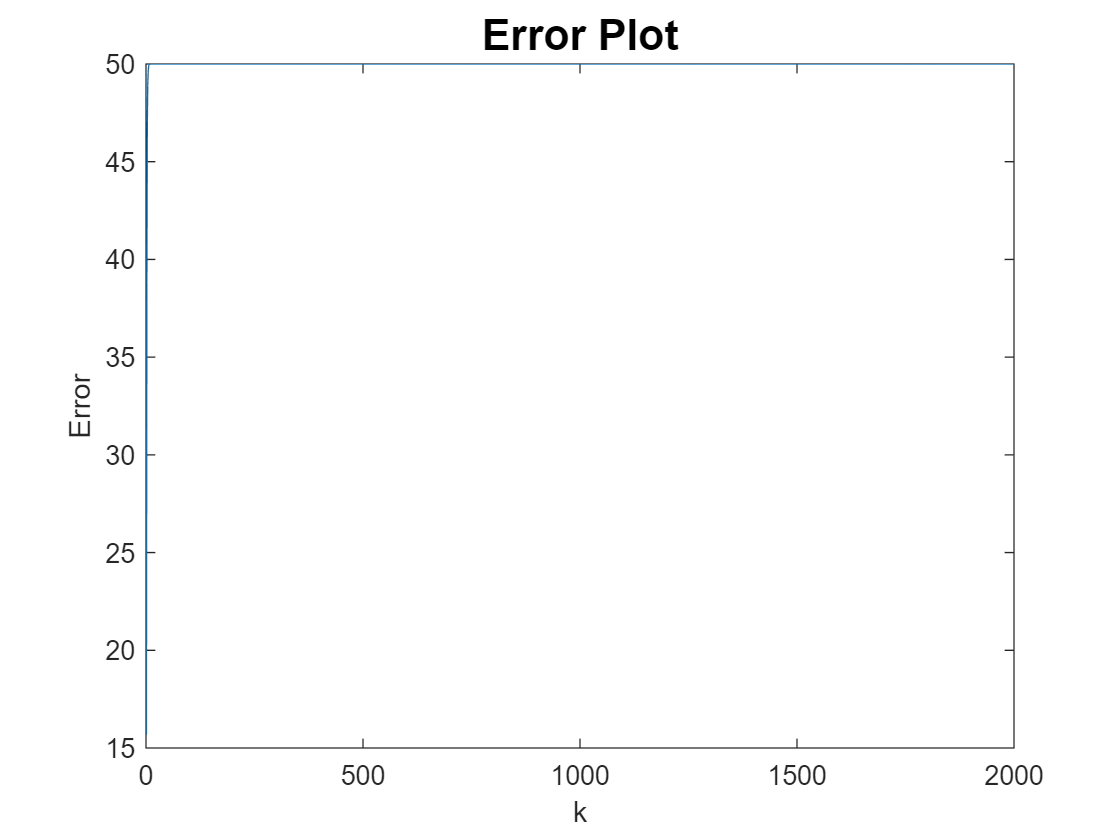

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

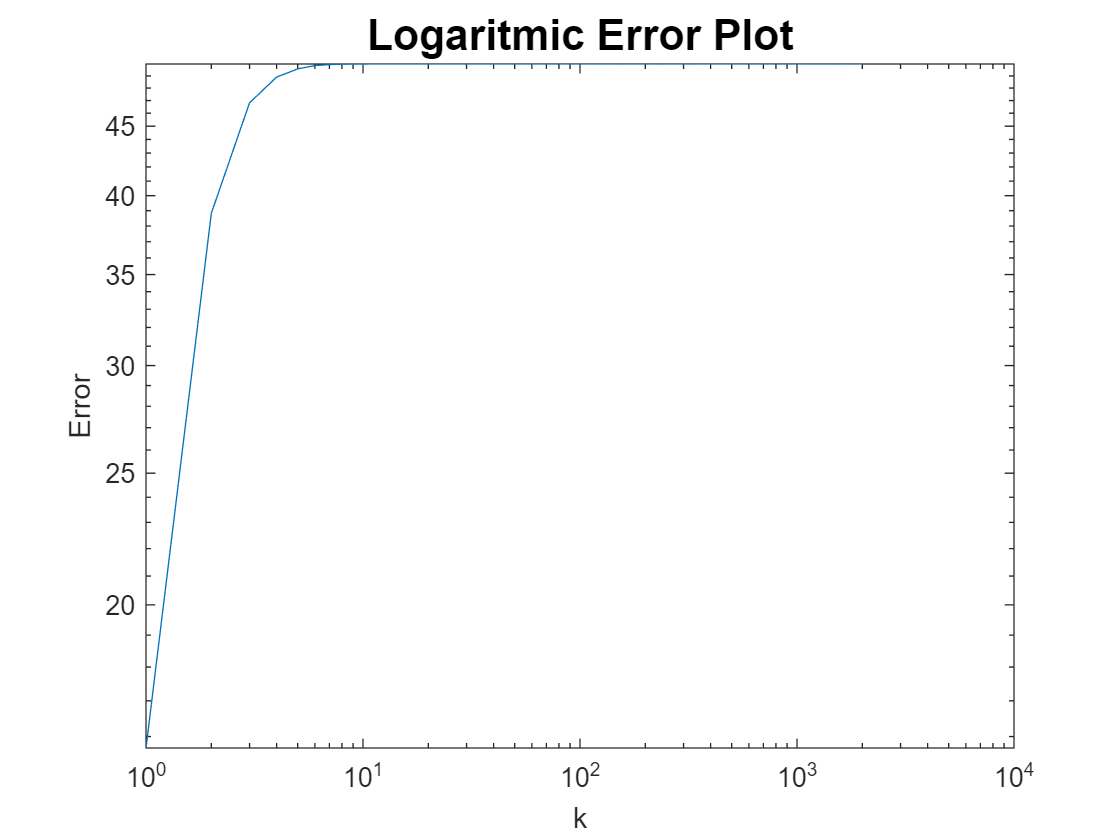

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

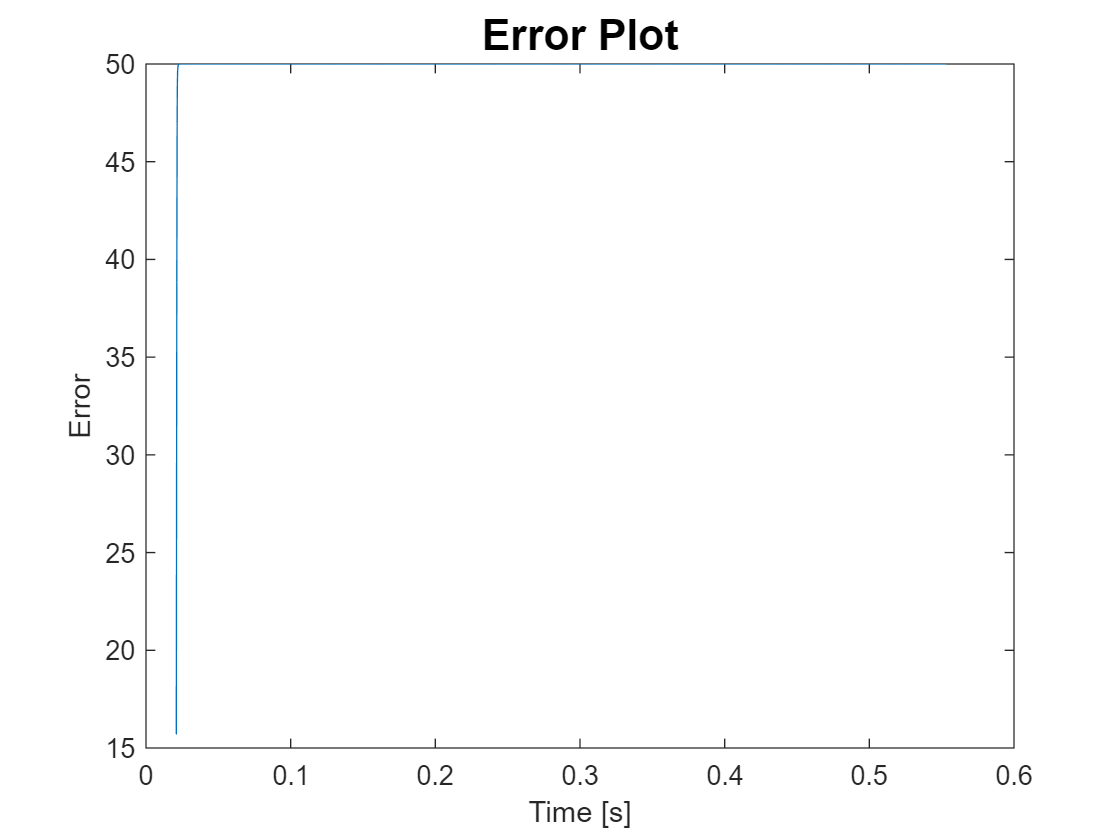

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

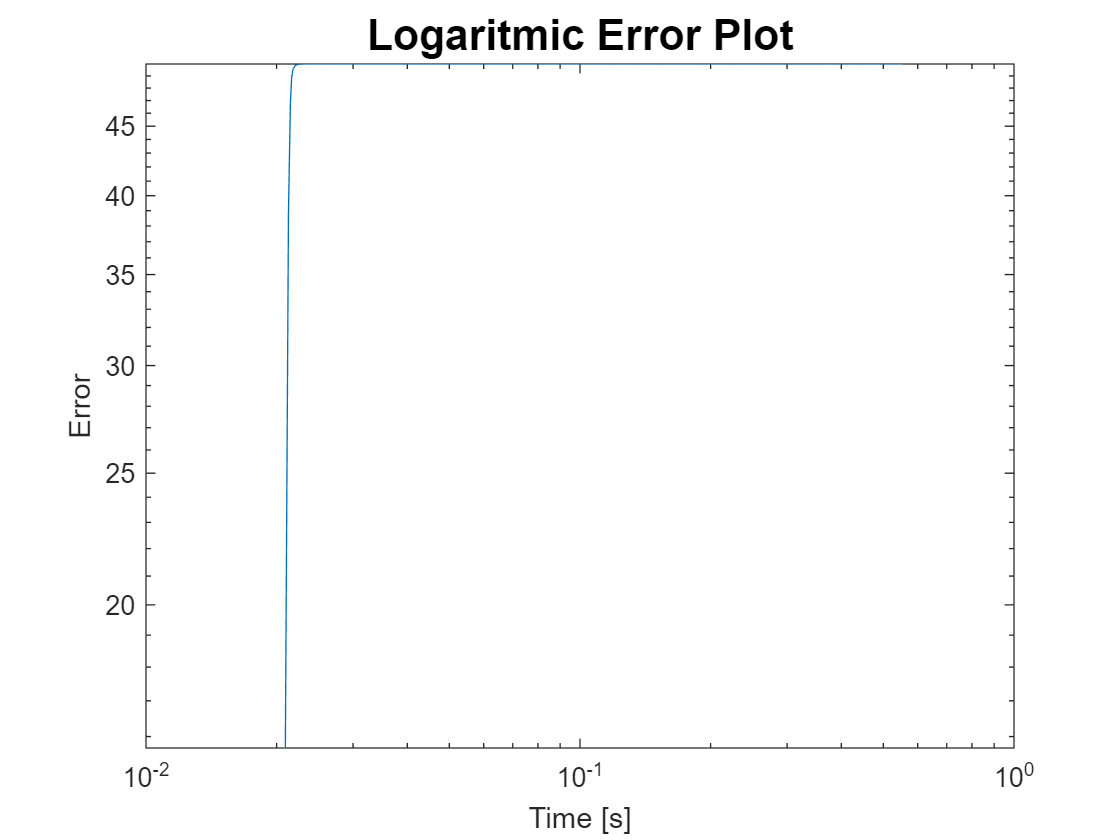

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^3

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad      c1      rho    btmax
    ____    ______    _______    ______    ___    _____

    100       5        1e-08     0.0001    0.5     500 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     -1.1071      0  
     -0.7854      0  
      -0.588      0  
    -0.46365      0  
    -0.38051      0  
    -0.32175      0  
     -0.2783      0  
    -0.24498      0  


tail(results_0, 8)

ans = 8×2 table
       xk        x_sol
    _________    _____

    -0.021502      0  
    -0.021273      0  
     -0.02105      0  
     -0.02083      0  
    -0.020616      0  
    -0.020405      0  
    -0.020199      0  
      0.78037      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
    fk     k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ___    __    __________    ______________    ___________    _______________    __________    _____________

    -50    30       102            501.41        4.7148e-09       2.2052e-09           50          0.031356   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 6×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

      20.68       0.081411      0.010099  
     49.997        0.48369      0.015058  
         50      -0.042481      0.019712  
         50        -1.5592      0.023723  
         50       0.061979        0.0275  
         50       -0.17587      0.031356  


tail(results_2, 8)

ans = 6×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

      20.68       0.081411      0.010099  
     49.997        0.48369      0.015058  
         50      -0.042481      0.019712  
         50        -1.5592      0.023723  
         50       0.061979        0.0275  
         50       -0.17587      0.031356  


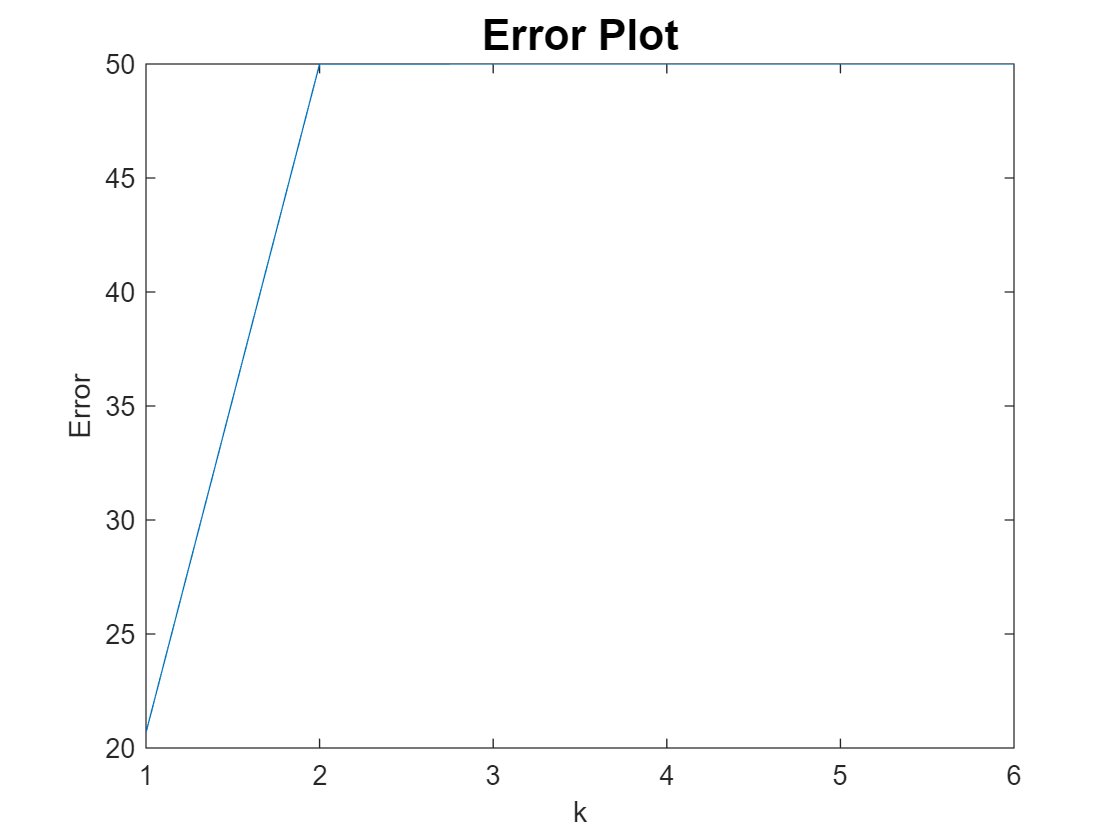

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

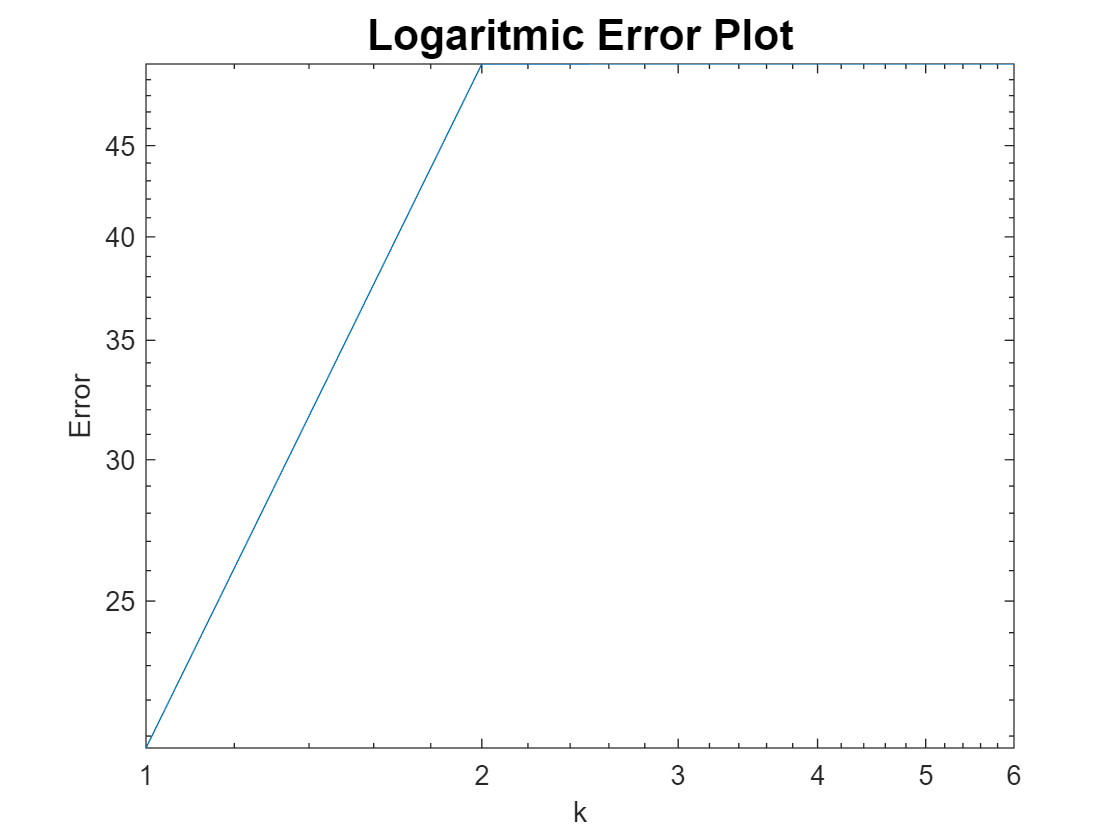

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

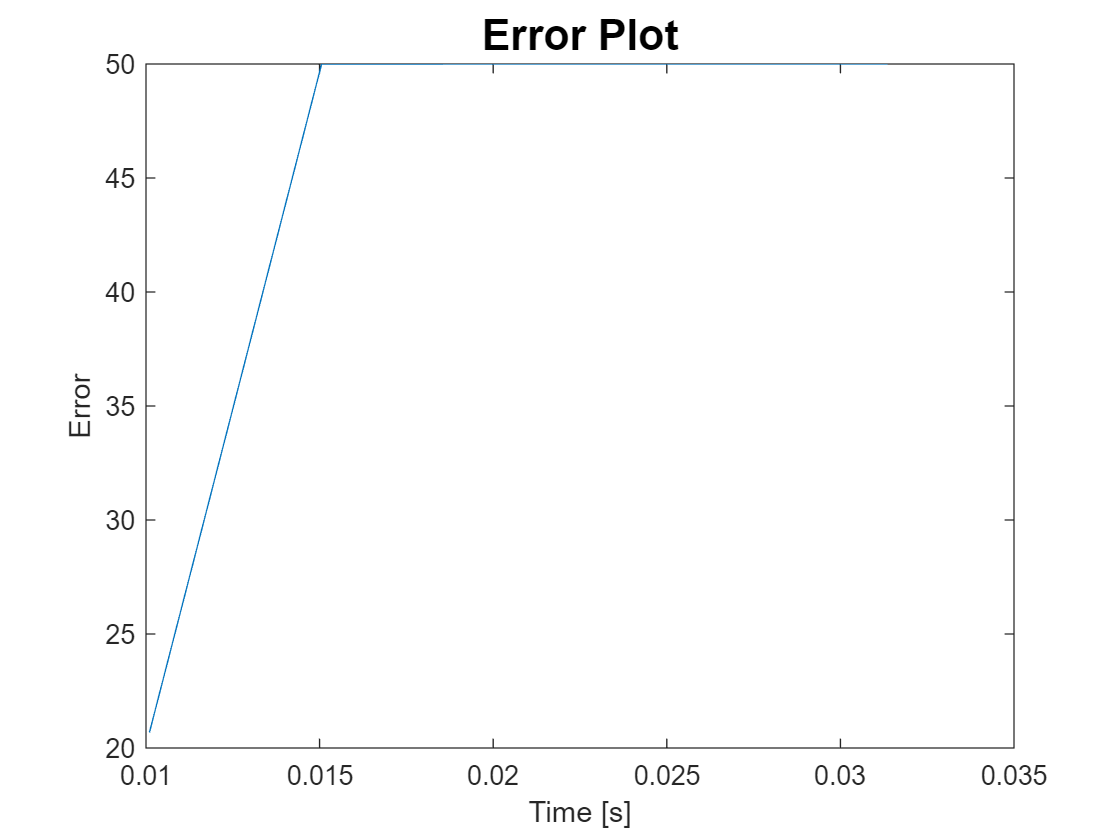

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

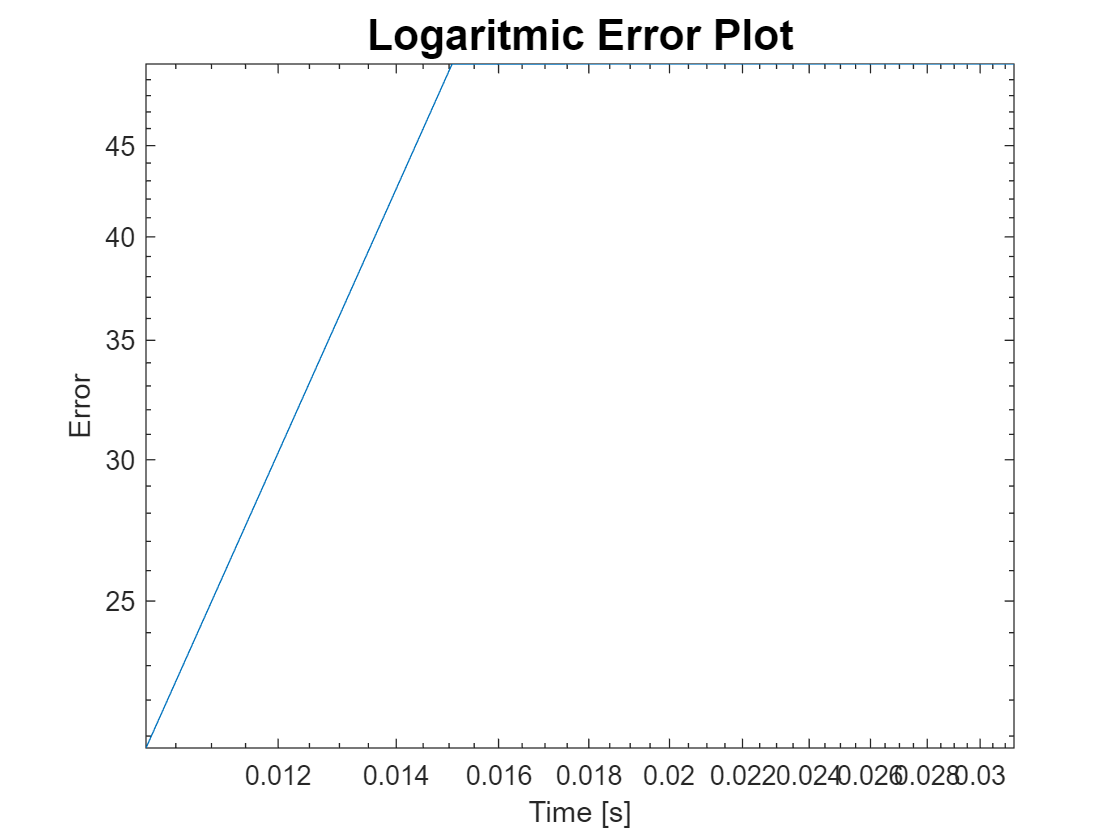

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^3

### Parameters

kmax = 5000;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad      c1      rho    btmax
    ____    ______    _______    ______    ___    _____

    5000      5        1e-08     0.0001    0.1     800 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     -7.3903      0  
     -0.7854      0  
      46.536      0  
      40.377      0  
      -38.08      0  
     -9.7465      0  
     -3.4199      0  
    -0.24498      0  


tail(results_0, 8)

ans = 8×2 table
       xk        x_sol
    _________    _____

    -0.021502      0  
    -0.021273      0  
     -0.02105      0  
     -0.02083      0  
    -0.020616      0  
    -0.020405      0  
    -0.020199      0  
      0.78037      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk      k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    __    ______________    ___________    _______________    __________    _____________

    13.761    14        501.41        2.0441e-13        2.025e-13         14.179        0.061338   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 2×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     40.396      0.050815       0.038866  
     14.179      -0.30372       0.061338  


tail(results_2, 8)

ans = 2×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     40.396      0.050815       0.038866  
     14.179      -0.30372       0.061338  


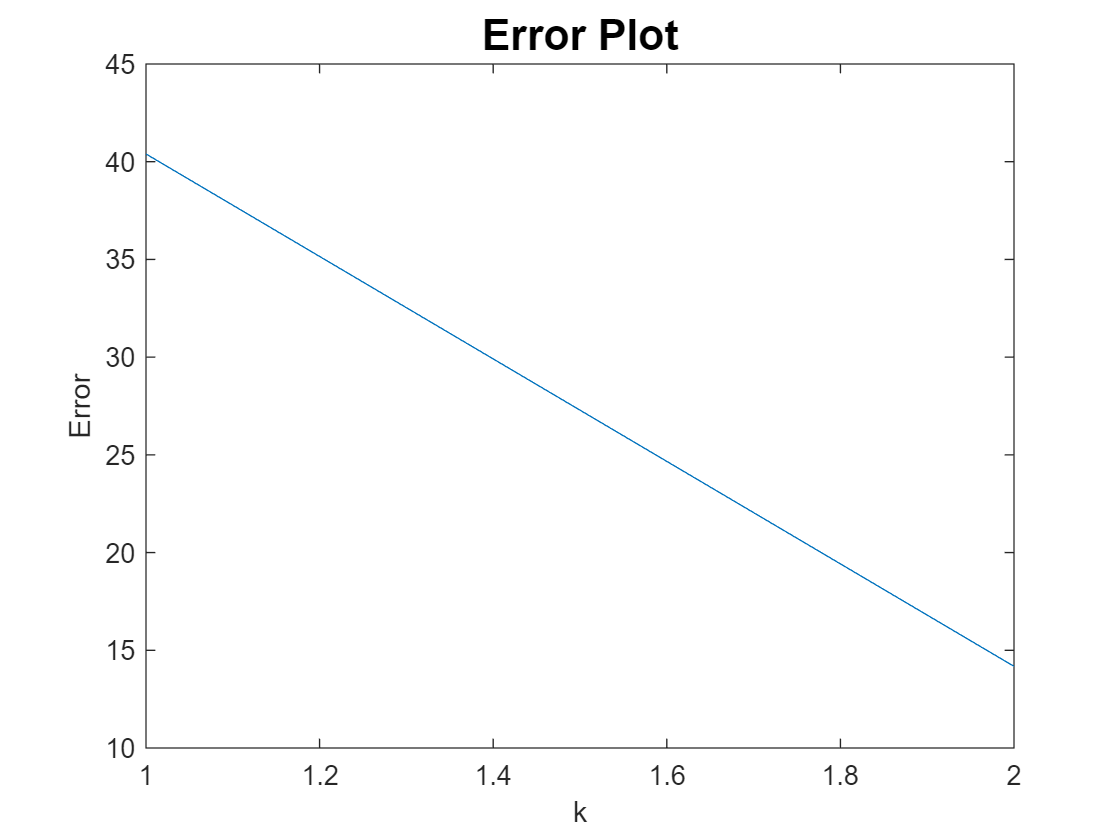

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

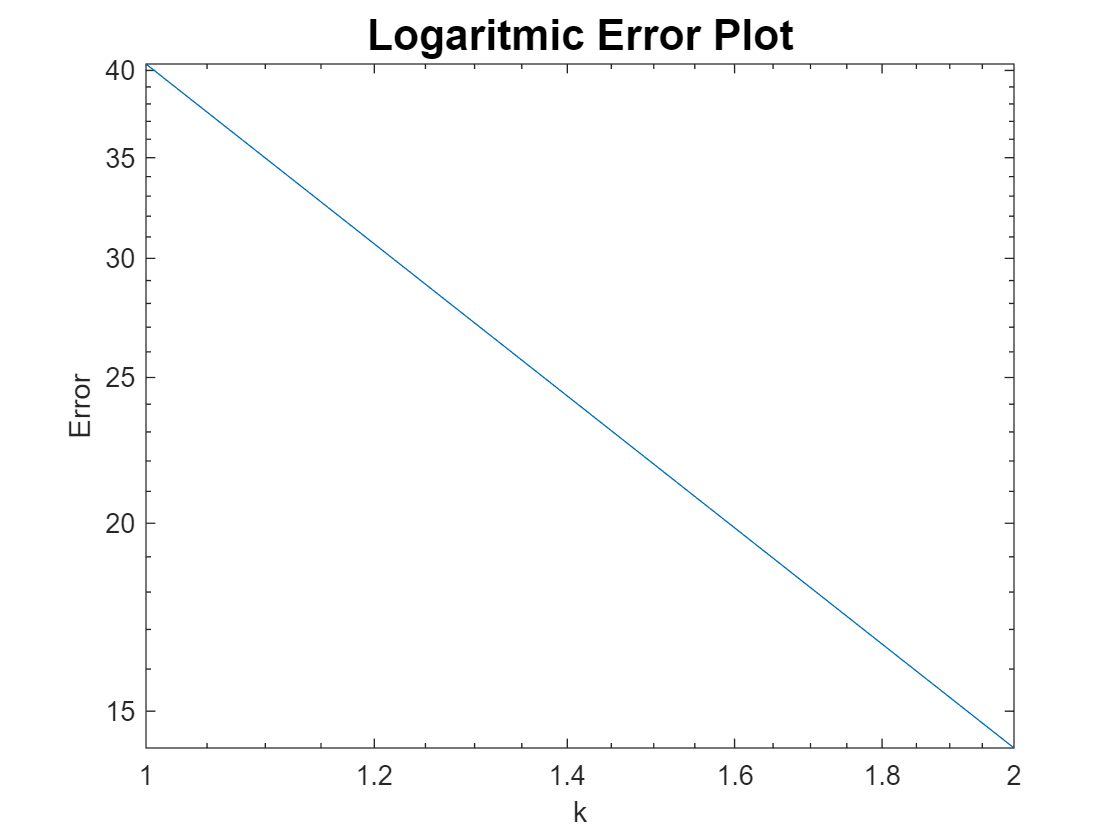

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

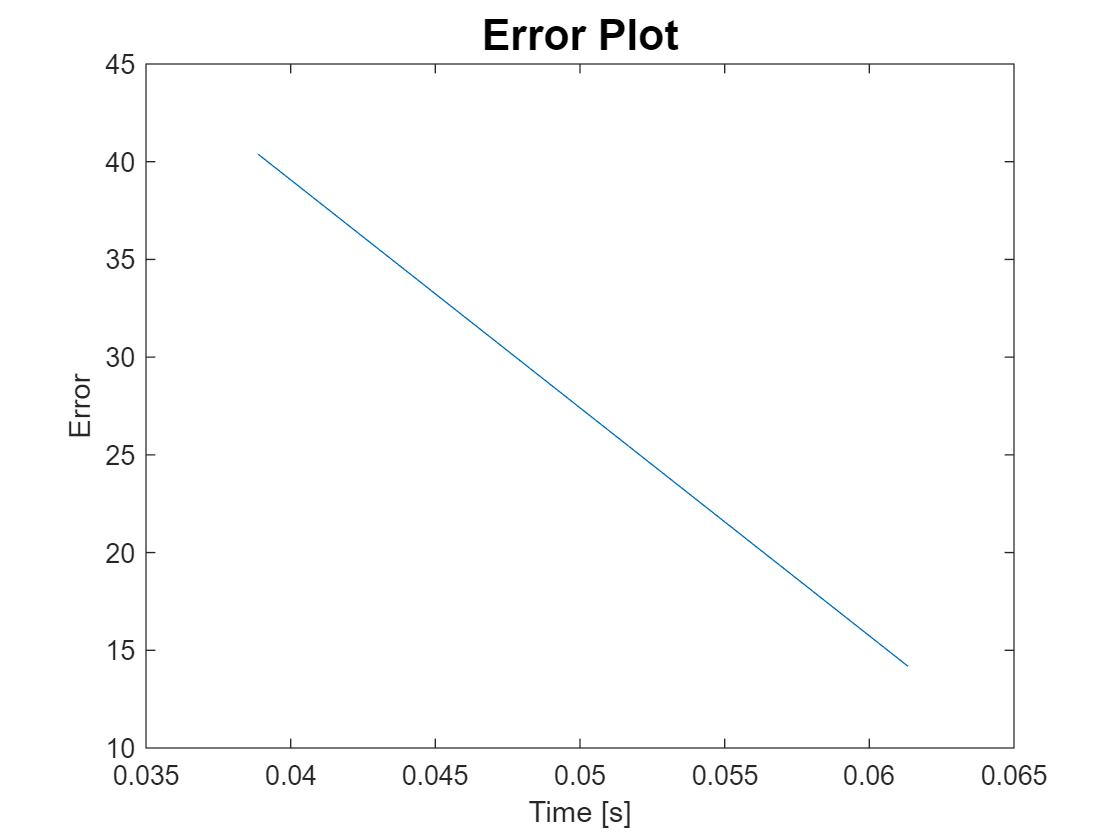

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

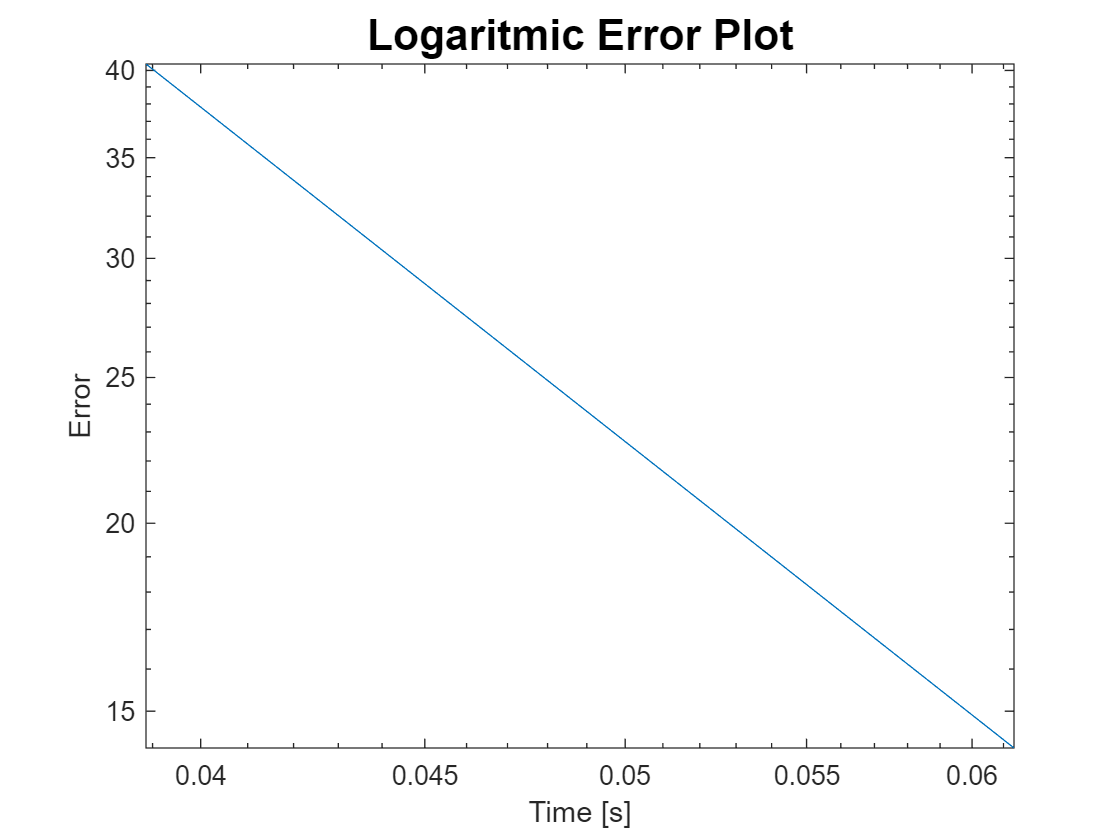

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Test function: Banded trigonometric problem - 10^4

% Dimension n (multiple of 2)
n = 10^4;  % 10^4;

% Initializations
x0 = zeros(n, 1);

% Generalization of the Brown function 1
f = @(x) banded_trigonometric(x);

% Starting point x0
x0(1) = 0;
for j = 2 : n-1
    x0(j) = 1;
end
x0(n) = 0;

% Expected solution
x_sol = zeros(1, n)';

% Gradient
gradf = @(x) banded_trigonometric_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 10000;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 1;  % initial step-length
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax     step_k    tolgrad      c1      rho    btmax
    _____    ______    _______    ______    ___    _____

    10000      5        1e-08     0.0001    0.1     800 


## Steepest descent method - 10^4

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     -1.1071      0  
     -0.7854      0  
      -0.588      0  
    -0.46365      0  
    -0.38051      0  
    -0.32175      0  
     -0.2783      0  
    -0.24498      0  


tail(results_0, 8)

ans = 8×2 table
       xk        x_sol
    _________    _____

    -0.021502      0  
    -0.021273      0  
     -0.02105      0  
     -0.02083      0  
    -0.020616      0  
    -0.020405      0  
    -0.020199      0  
      0.78037      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
    fk       k      gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ___    _____    ______________    ___________    _______________    __________    _____________

    -50    10000        501.41        1.1092e-06       8.0539e-07           50           0.50793   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     15.693       0.78092       0.0020763 
     38.823       0.78256        0.002191 
      46.82       -12.188       0.0022908 
     48.906       0.66353       0.0023826 
     49.584        7.0026       0.0024679 
     49.867      -0.31726       0.0025593 
     49.952       0.59784       0.0026487 
     49.981       0.68866        0.002737 


tail(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

       50           NaN          0.50628  
       50           NaN           0.5065  
       50           NaN          0.50671  
       50           NaN          0.50692  
       50           NaN          0.50712  
       50           NaN          0.50733  
       50           NaN          0.50754  
       50           NaN          0.50793  


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

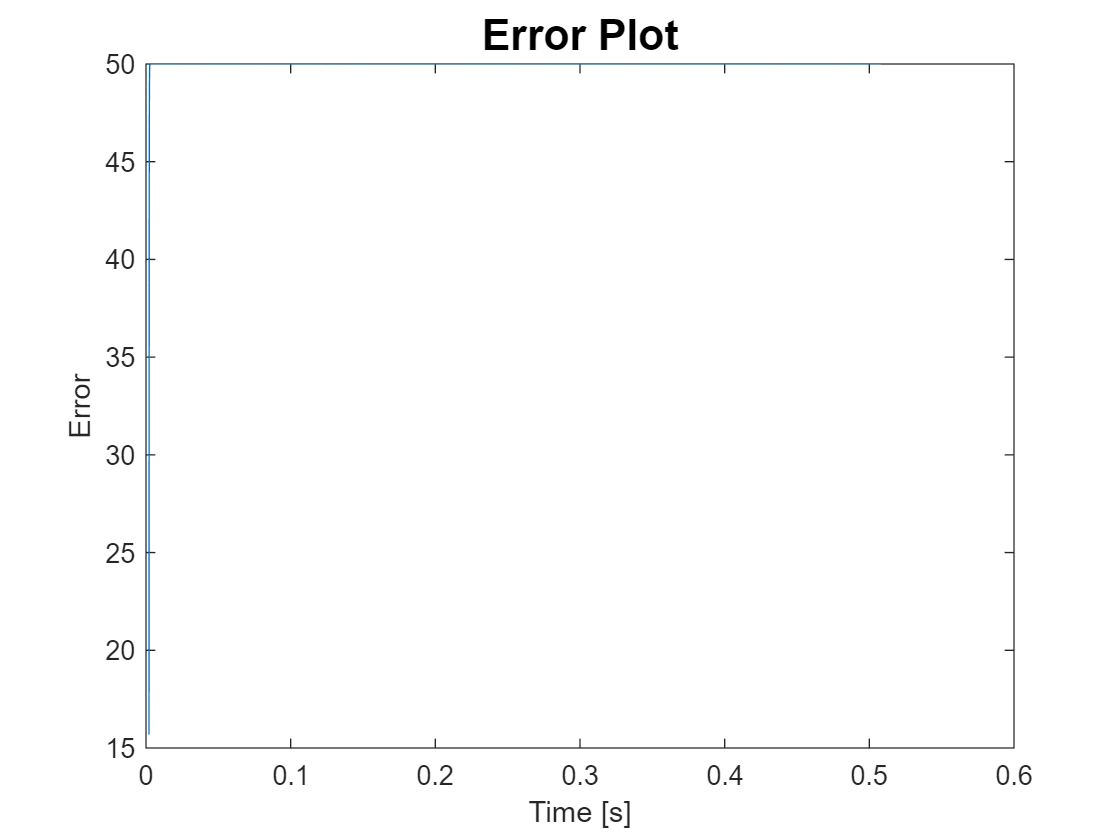

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

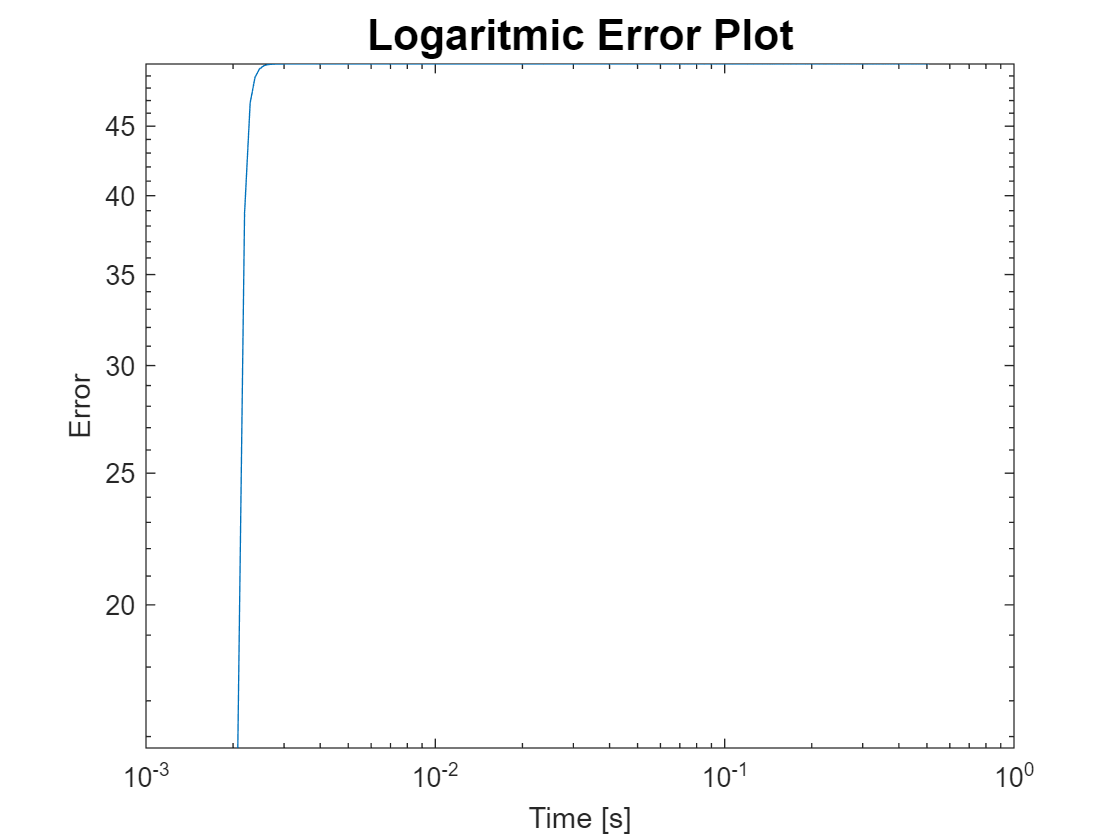

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^4

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad      c1      rho    btmax
    ____    ______    _______    ______    ___    _____

    100       5        1e-08     0.0001    0.5     500 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     -1.1071      0  
     -0.7854      0  
      -0.588      0  
    -0.46365      0  
    -0.38051      0  
    -0.32175      0  
     -0.2783      0  
    -0.24498      0  


tail(results_0, 8)

ans = 8×2 table
       xk        x_sol
    _________    _____

    -0.021502      0  
    -0.021273      0  
     -0.02105      0  
     -0.02083      0  
    -0.020616      0  
    -0.020405      0  
    -0.020199      0  
      0.78037      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
    fk     k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ___    __    __________    ______________    ___________    _______________    __________    _____________

    -50    30       102            501.41        4.7148e-09       2.2052e-09           50          0.030779   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 6×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

      20.68       0.081411      0.0057455 
     49.997        0.48369      0.0096247 
         50      -0.042481       0.014186 
         50        -1.5592       0.020616 
         50       0.061979       0.026774 
         50       -0.17587       0.030779 


tail(results_2, 8)

ans = 6×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

      20.68       0.081411      0.0057455 
     49.997        0.48369      0.0096247 
         50      -0.042481       0.014186 
         50        -1.5592       0.020616 
         50       0.061979       0.026774 
         50       -0.17587       0.030779 


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

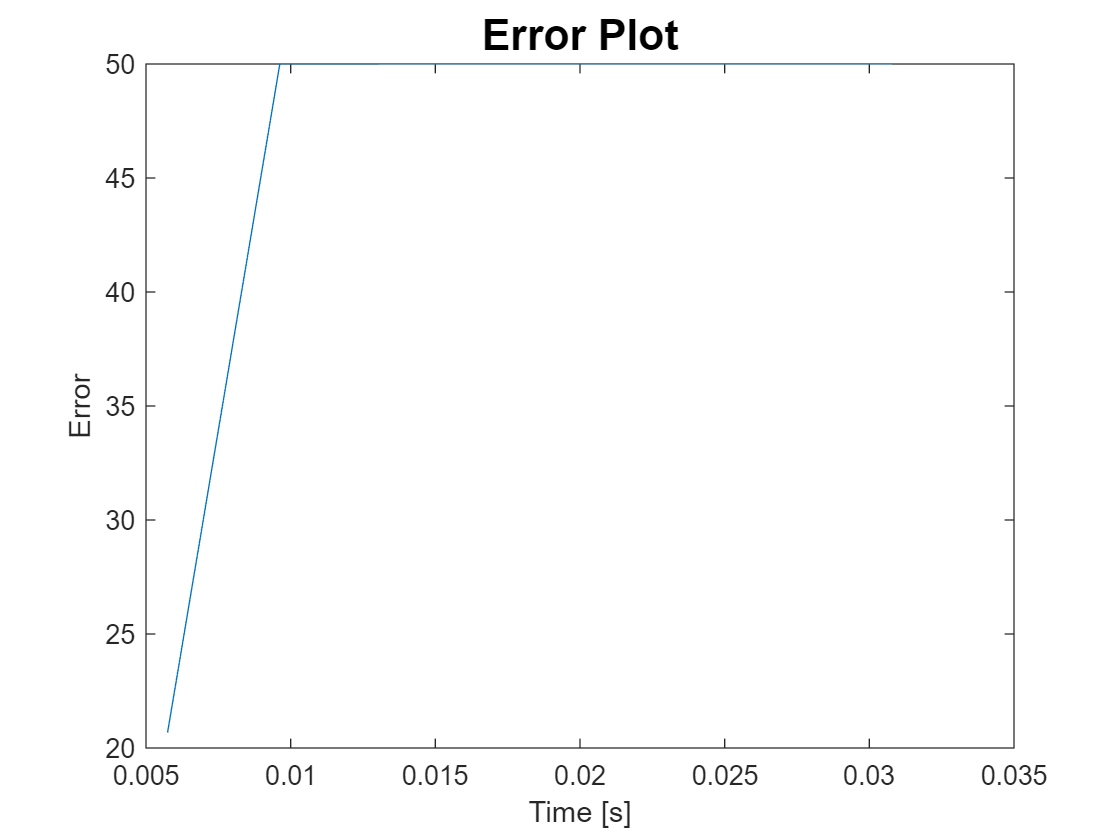

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

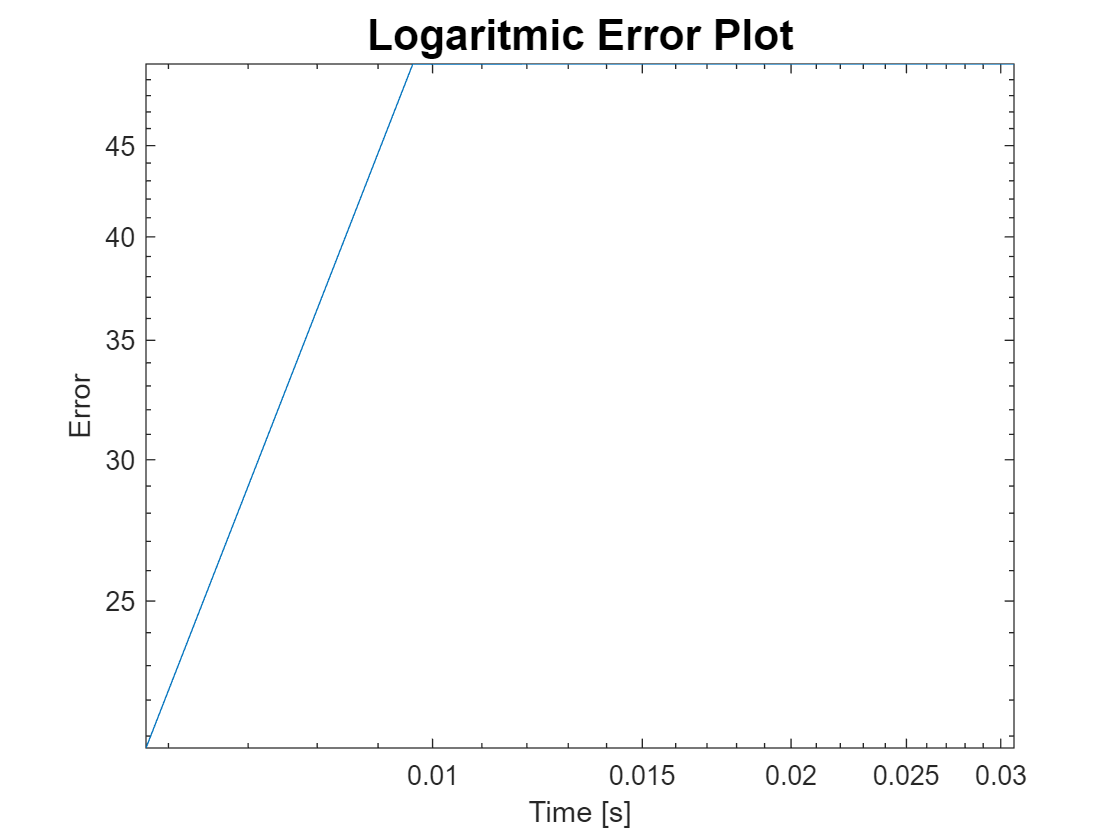

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^4

### Parameters

kmax = 5000;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-1;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 1000;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad    c1     rho    btmax
    ____    ______    _______    ___    ___    _____

    5000      5        1e-08     0.1    0.1    1000 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     -7.3903      0  
     -0.7854      0  
      46.536      0  
      40.377      0  
      -38.08      0  
     -9.7465      0  
     -3.4199      0  
    -0.24498      0  


tail(results_0, 8)

ans = 8×2 table
       xk        x_sol
    _________    _____

    -0.021502      0  
    -0.021273      0  
     -0.02105      0  
     -0.02083      0  
    -0.020616      0  
    -0.020405      0  
    -0.020199      0  
      0.78037      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk      k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    __    ______________    ___________    _______________    __________    _____________

    13.761    14        501.41        2.0441e-13        2.025e-13         14.179        0.062642   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 2×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     40.396      0.050815        0.03962  
     14.179      -0.30372       0.062642  


tail(results_2, 8)

ans = 2×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     40.396      0.050815        0.03962  
     14.179      -0.30372       0.062642  


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

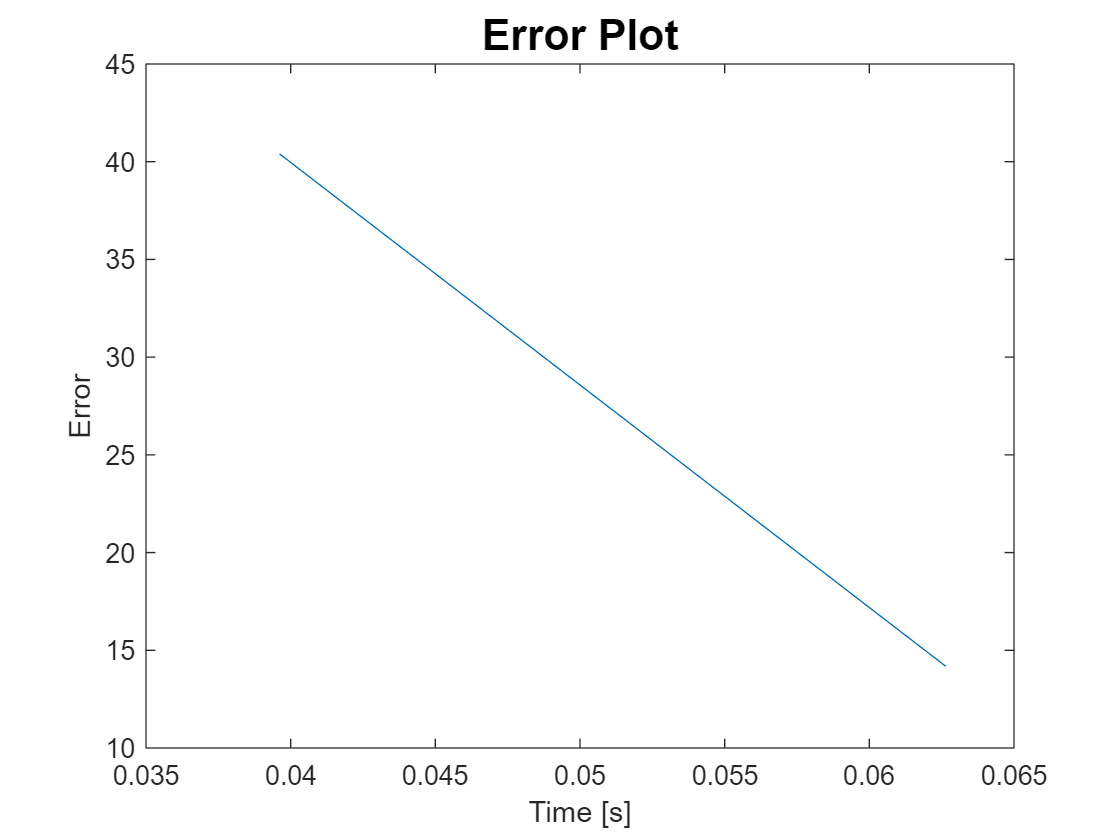

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

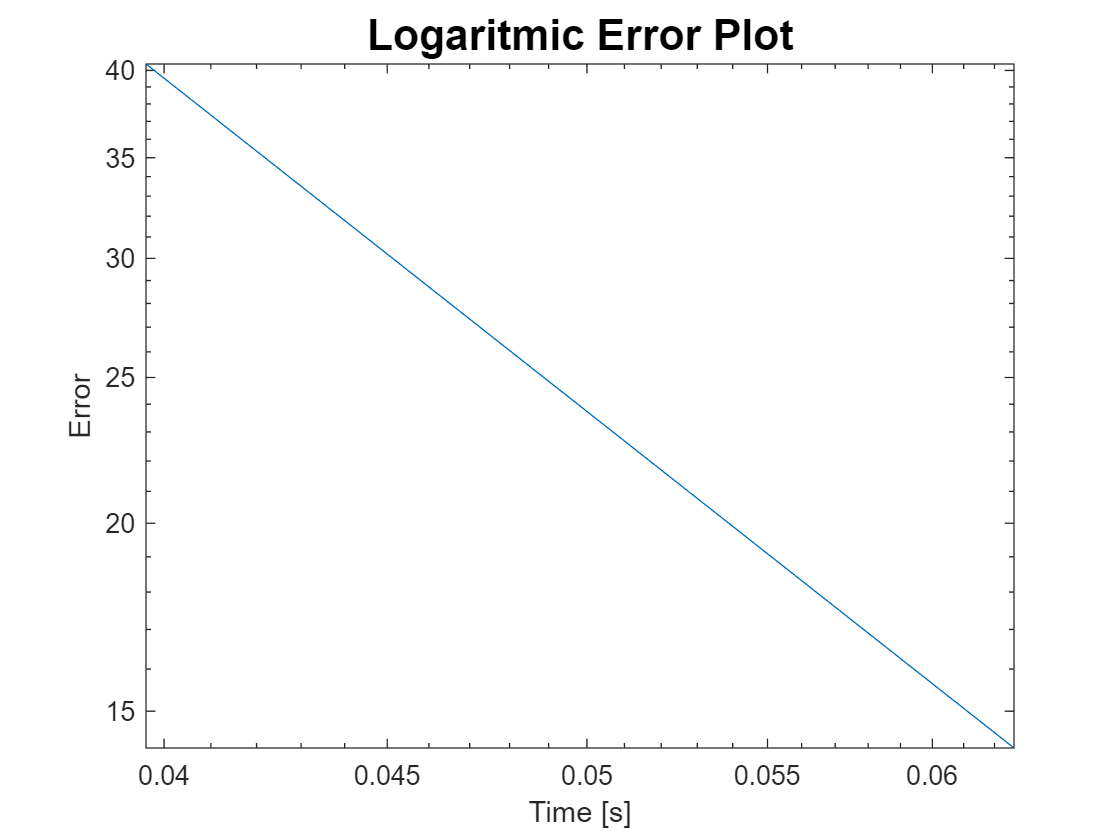

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')